# **TU: Frequecy Features Extraction**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

Prerequisite:  Review how to apply one-single sided power using FFT 

Frequency Features of 

- Frequency Center

- RMS frequency

- Root variance frequency

> Need to use  getFFT.m   

## Include path

addpath('../../Library')  

## Dataset

### Generate Signals

A signal with a sampling frequency of 1 kHz and a signal duration of 1 second.

Form a signal containing a 50 Hz sinusoid and 120Hz sinusoid 

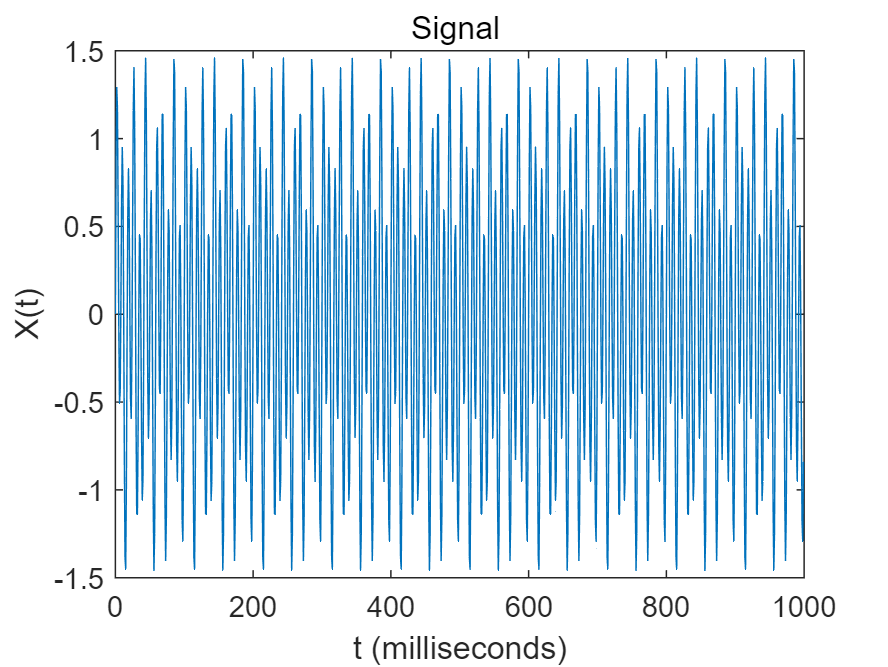

close all
clear 

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = 1000;             % Length of signal
t = (0:N-1)*T;        % Time vector


% Information Signal 
fa=50;      % 10Hz signal
fa2=120;    % 55Hz signal
X = 0.0 + 0.5* sin(2.0*pi*fa*t)+1*sin(2.0*pi*fa2*t); 

% Plot signals
figure()
plot(1000*t,X)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('X(t)')

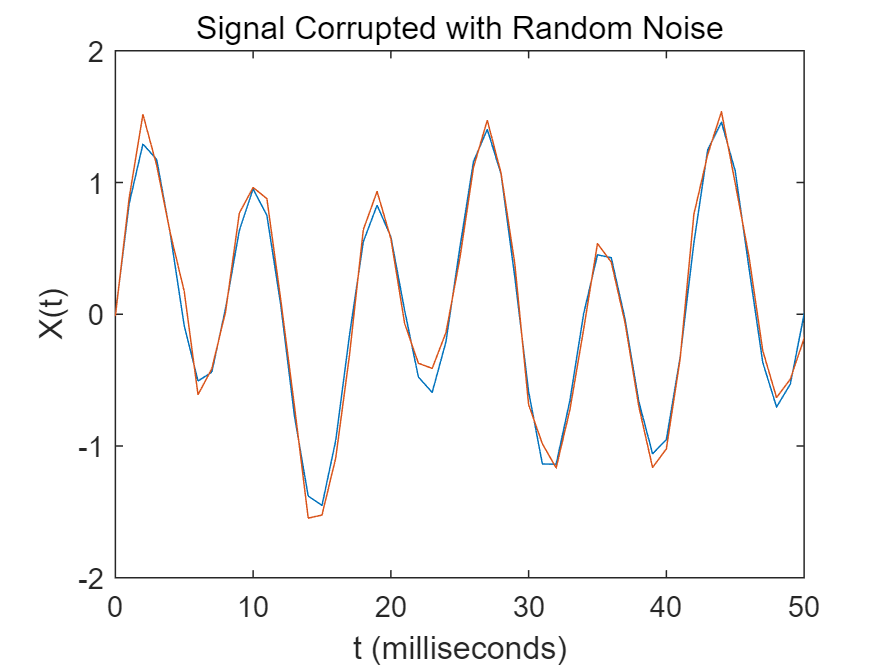

% Noise
noise=0.1*randn(size(t));

% Mixed Signal
Xm = X+noise; 


% Plot signals
figure(1)
plot(1000*t,X, 1000*t,Xm)
title('Signal Corrupted with Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
xlim([0 50])

## Exercise 1: Frequency Features (simple)

- Frequency Center

- RMS frequency

- Root variance frequency

### 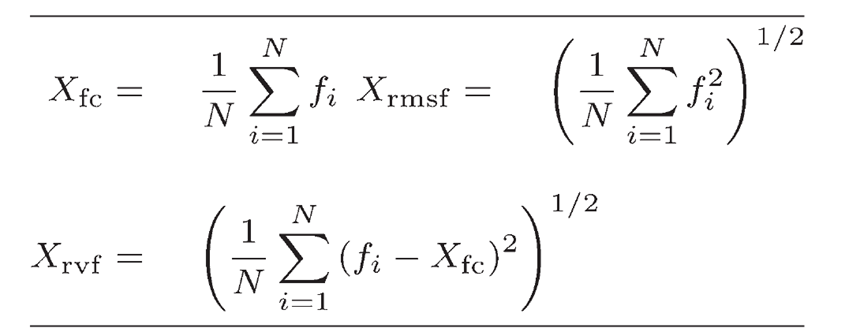

### FFT analysis

%%% Input for FFT
x=X;    %x=Xm;
L=length(x);

%%% Apply FFT of x
% single-sided spectrum P1
% YOUR CODE GOES HERE
% P=_______________
f = 0:Fs/L:Fs/2;  


Plot single-sided spectrum P

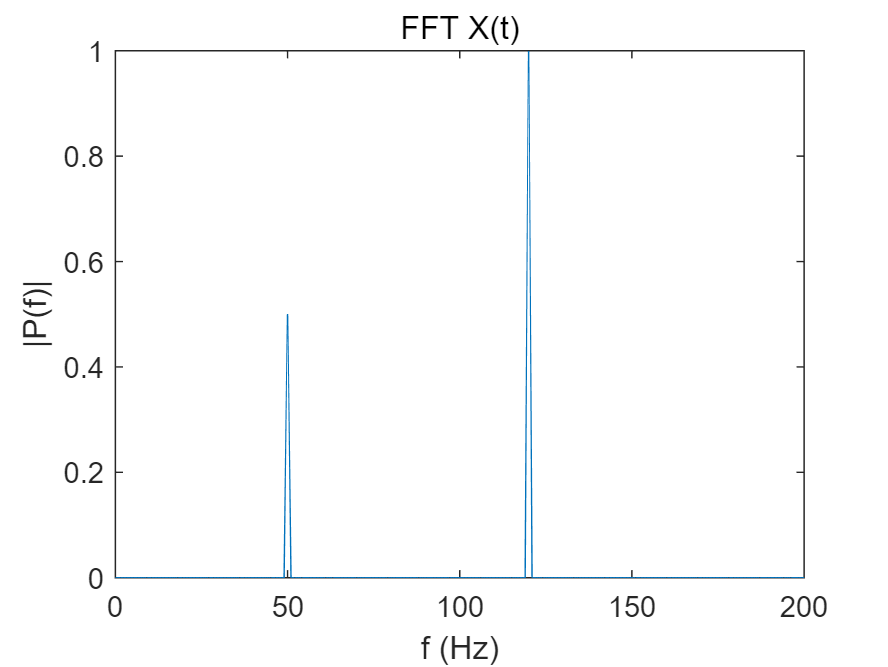

figure
plot(f,P) 
title('FFT X(t)')
xlabel('f (Hz)')
ylabel('|P(f)|')

xlim([0 200])

### Frequency features

% x:        Input data
% xfeature: Table for feature of x


F=P;        %=Xm
N=length(F);

% Create table variable xfeature
xfeature = table;

**Frequency Center**

% YOUR CODE GOES HERE
% xfeature.fc=______________

**RMS frequency**

% YOUR CODE GOES HERE
% xfeature.rmsf=_____________

**Root variance frequency**

% YOUR CODE GOES HERE
% xfeature.rvf=_____________

## Exercise 2

Compare the  features of signals with and without noise added.

## Exercise 3

Create a module, named as `freqFeatures.m` that returns time-domain features in table form.

Save it in `\IAIA\Library\` folder

See [**freqFeatures_student.m**](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Library) as an example.

Example: 

% Given P=getFFT(x,L);
% YOUR CODE GOES HERE
xfeature2=freqFeatures(P)

xfeature2 = 1×3 table
        fc         rmsf        rvf  
    __________    _______    _______

    -2.176e-17    0.79057    0.79096
